# Simulate Building Energy Management System

Copyright 2024 - 2025 The MathWorks, Inc.

In this workflow, you learn how to parameterize and prepare a model for detailed Building Management System (BMS) simulations. The end of the workflow results in a parameterized model for you to review and run based on your requirements. This example demonstrates how to set up and use the model with various room HVAC configurations: `Room Radiator Only,` `Room Underfloor Heating/Cooling Only`, or `Room Radiator with Underfloor Heating/Cooling`. You will learn how to size radiators or underfloor piping differently for each room, control fluid valves for rooms, and calculate actual power consumption in the system under realistic load conditions.

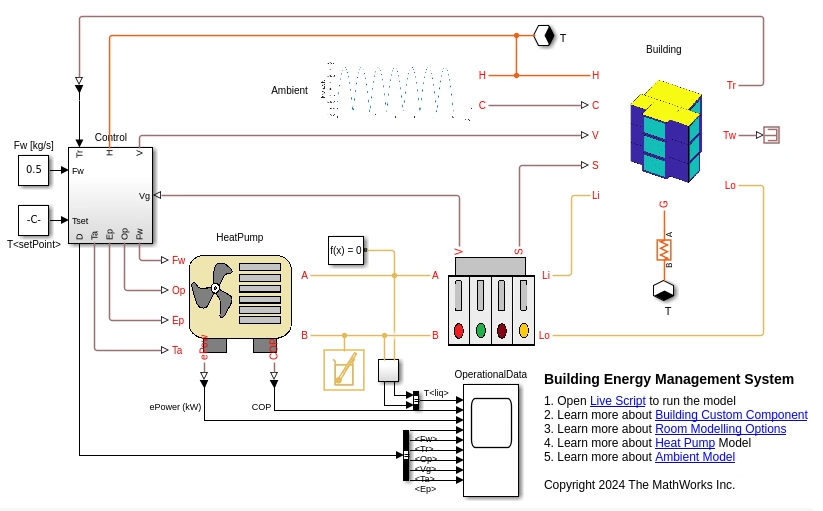

This picture illustrates the basic setup you will use in this example. The **Building** component is connected to the **Ambient** and the **HeatPump** components through the **OperationalData** block. The bundle of Simscape thermal liquid nodes from the building connects to a single thermal liquid node at the **OperationalData** block. The **Control** subsystem models the opening or closing of room valves based on operational parameters and other measurements. You can use this model as a starting point to develop your network and analyze actual energy consumption.

## Read Building Data

Load the building data with solar load from the `building_with_solar_load` XML file.

[apartment3D, geoLocation, dateTimeVec] = ...
    readBuildingDataXML(FileName="building_with_solar_load.xml");

    {'Location:Bengaluru'}

Simulation Duration:
*** Start Time :01-May-2024 01:00:00
*** End Time   :07-May-2024 01:00:00
*** Room Names in Building : FireExit,Bathroom,Kitchen,Bedroom,LivingRoom


Set viewing direction for all 3D plots.

viewingAngle = [-1 -1 1]; 

Plot the building and create an icon for the building custom model in Simscape.

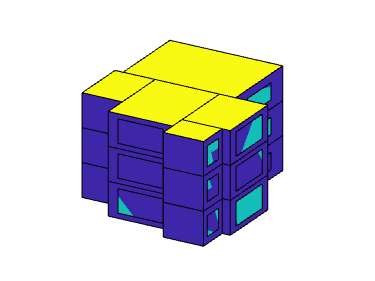

createIconBuildingCustomComponent(Building=apartment3D,...
                                  PlotViewDirection=viewingAngle);


nDays = days(dateTimeVec(1,end)-dateTimeVec(1,1));

hoursTracked = hour(dateTimeVec(1:end));
disp(strcat("Number of hours of simulation = ",num2str(length(hoursTracked))));

Number of hours of simulation = 145


## Parameterize model

### Initialize Model Parameters

The function `initializeBuildingSimulationParameters` initializes the parameter required by the model and returns them in data struct `physTable` and `opsParams`. 

- You must specify the average day-time temperatures `DayTemperature`, average night-time temperatures `NightTemperature`, and the percentage variation of temperature from the average (`DayTemperatureVar` and `NightTemperatureVar`). You must provide these average temperatures for all days, `nDays`, as included in the building data XML part file. 

- The building desired set point temperature is specified by the name value pair `RoomTsetPoint`.

- The heat load per occupant in the room f a building is specified by the name value pair of `HeatLoadPerPerson`.

[physTable,opsParams] = initializeBuildingSimulationParameters(...
                        Building=apartment3D,...
                        DateTimeVec=dateTimeVec,...
                        Location=geoLocation,...
                        GroundResistance=simscape.Value(100,"K/W"),...
                        RoomTsetPoint=simscape.Value(293,"K"),...
                        DayTemperature=simscape.Value(303*ones(1,nDays),"K"),...
                        DayTemperatureVar=1,...
                        NightTemperature=simscape.Value(299*ones(1,nDays),"K"),...
                        NightTemperatureVar=1,...
                        HeatLoadPerPerson=simscape.Value(50,"W"));

### Specify Detailed HVAC Layout Parameters

You can select one of the 3 detailed HVAC modelling options:

- `Thermal Management: Radiator Model`: Room is modelled as a thermal mass with a coupled radiator model. 

- `Thermal Management: Under Floor Model`: Room is modelled as a thermal mass with coupled underfloor piping thermal model. 

- `Thermal Management: Radiator and Under Floor Model`: Room is modelled as a thermal mass with coupled radiator model and underfloor piping thermal model. 

To learn more about different room fidelity options, see [Room Modelling Options](matlab:open('../Overview/html/DocumentationRoomModellingOptions.html')). In this example, you will learn how to use the 3rd option for HVAC modelling. By default, all rooms have the same configuration:

- **Radiator**: The radiator front area is set in comparison to the largest wall in the room. The default configuration specifies that the radiator spans 25% of the largest wall area.

- **Underfloor Piping**: The underfloor piping coverage is specified in comparison to the room's floor. The default setting covers 100% of the floor area, which means that the underfloor piping extends across the entire floor area.

For all floor levels, adjust the underfloor piping area to cover 50%  of the total floor area for the Kitchen and Bathroom only. Change the default values for underfloor cooling/heating area by changing the parameter `Underfloor Coverage Area Fraction`.

buildingDataStruct = ...
    editHVACModelParameterRoom(Building=apartment3D,...
                               ListOfLevels=(1:3)',...
                               ListOfRooms=["Kitchen";"Bathroom"],...
                               ModelParameter="Underfloor Coverage Area Fraction",...
                               NewValue=0.9);

### Specify HVAC Operational Data

Change operational data for HVAC system and switch off HVAC when not needed. For all building floors from 1st till the 3rd and datetime specified by dateTimeVec(7:13), switch of the HVAC requirement for all rooms, the *BedRoom*, the *LivingRoom*, the *Kitchen*, and the *Bathroom*.

physTable = editParametersForBuildingPhysics(PhysicsTable=physTable,...
                                             ListOfLevels=(1:3)',...
                                             ListOfRooms=["Bedroom"; "LivingRoom"; "Kitchen"; "Bathroom"],...
                                             ListOfTimeValues=dateTimeVec(7:13),...
                                             PhysicsParameter="HVAC On",...
                                             NewValue=false);

For all the given Room List & DateTimeVector, HVAC On = 0
 
Updated Physics Table:
 
       Date and Time        Level    Apartment    Room     Room Name      HVAC On    Heat Source (W)    Electrical Load (W)    Room Occupancy Level
    ____________________    _____    _________    ____    ____________    _______    _______________    ___________________    ____________________

    01-May-2024 01:00:00      1          1         1      "LivingRoom"     true             0                    0                      0          
    01-May-2024 01:00:00      1          1         2      "Bedroom"        true             0                    0                      0          
    01-May-2024 

### Specify Room Occupancy Data

Add room occupancy data for the simulation duration. 

- For certain specified datetime values, as defined by dateTimeVec([1:3,15:end]), set the room occupancy level for each *Bedroom* on the 2nd floor of the building as 2.

    physTable = editParametersForBuildingPhysics(PhysicsTable=physTable,...
                                                 ListOfLevels=2,...
                                                 ListOfRooms="Bedroom",...
                                                 ListOfTimeValues=dateTimeVec([1:3,15:end])',...
                                                 PhysicsParameter="Room Occupancy Level",...
                                                 NewValue=2);

For all the given Room List & DateTimeVector, Room Occupancy Level = 2
 
Updated Physics Table:
 
       Date and Time        Level    Apartment    Room     Room Name      HVAC On    Heat Source (W)    Electrical Load (W)    Room Occupancy Level
    ____________________    _____    _________    ____    ____________    _______    _______________    ___________________    ____________________

    01-May-2024 01:00:00      1          1         1      "LivingRoom"     true             0                    0                      0          
    01-May-2024 01:00:00      1          1         2      "Bedroom"        true             0                    0                      0          
   

- For certain specified datetime values, as defined by dateTimeVec(14), set the room occupancy level for each *Kitchen* on the 3rd floor of the building as 2.

    physTable = editParametersForBuildingPhysics(PhysicsTable=physTable,...
                                                 ListOfLevels=1,...
                                                 ListOfRooms="LivingRoom",...
                                                 ListOfTimeValues=dateTimeVec(4:6)',...
                                                 PhysicsParameter="Room Occupancy Level",...
                                                 NewValue=1);

For all the given Room List & DateTimeVector, Room Occupancy Level = 1
 
Updated Physics Table:
 
       Date and Time        Level    Apartment    Room     Room Name      HVAC On    Heat Source (W)    Electrical Load (W)    Room Occupancy Level
    ____________________    _____    _________    ____    ____________    _______    _______________    ___________________    ____________________

    01-May-2024 01:00:00      1          1         1      "LivingRoom"     true             0                    0                      0          
    01-May-2024 01:00:00      1          1         2      "Bedroom"        true             0                    0                      0          
   

- For certain specified datetime values, as defined by dateTimeVec(4:6), set the room occupancy level for each *LivingRoom* on the 1st floor of the building as 1.

    physTable = editParametersForBuildingPhysics(PhysicsTable=physTable,...
                                                 ListOfLevels=3,...
                                                 ListOfRooms="Kitchen",...
                                                 ListOfTimeValues=dateTimeVec(14)',...
                                                 PhysicsParameter="Room Occupancy Level",...
                                                 NewValue=2);

For all the given Room List & DateTimeVector, Room Occupancy Level = 2
 
Updated Physics Table:
 
       Date and Time        Level    Apartment    Room     Room Name      HVAC On    Heat Source (W)    Electrical Load (W)    Room Occupancy Level
    ____________________    _____    _________    ____    ____________    _______    _______________    ___________________    ____________________

    01-May-2024 01:00:00      1          1         1      "LivingRoom"     true             0                    0                      0          
    01-May-2024 01:00:00      1          1         2      "Bedroom"        true             0                    0                      0          
   

You can also apply 24-hour repeating data to the physTable through use of function apply24HrsDataForAllDaysToBuildingPhysics. See workflow [Building Load Heat Estimation](matlab:open('./BuildingHeatLoadEstimation.mlx')) or [Function Reference List](matlab:open('../Overview/html/FunctionReferenceList.html')) for more on the same.

### Specify Building Material Data

buildingMaterial = initializeBuildingMaterialProperties(DisplayData=true);

*** You must not specify values marked as NaN in the table.
*** Block default values are provided where name-value-pair are not defined.
                                    Roof    Floor    ExternalWall    InternalWall    Window
                                    ____    _____    ____________    ____________    ______

    Absorptivity [-]                 0.6     NaN          0.6             NaN          0.4 
    Transmissivity [-]               NaN     NaN          NaN             NaN          0.2 
    Thickness [m]                    0.3     0.3          0.3             0.3         0.01 
    Density [kg/m^3]                2400    2400         2400            2400         4000 
    Heat Capacity [J/kg-K]           750     750       

The function above defines some default values for the building wall, roof, floor, and windows. You can use name value pair arguments for the above function to change any building material property. See [Function Reference List](matlab:open('../Overview/html/FunctionReferenceList.html')) for more on the same.

## Open Model to Run

Collate all building thermal network related parameters.

bldgThermalNetwork = getParamsForSimscapeComponent(Building=buildingDataStruct,...
                                                   PhysicsTableData=physTable,...
                                                   OperationalData=opsParams);

Setup parameterized model for simulations.

mdl = setParametersForBuildingCustomComponent(Building=buildingDataStruct,...
                                              BuildingNetworkData=bldgThermalNetwork,...
                                              RoomModel="HVAC: Room Radiator with Underfloor Heating/Cooling",...
                                              Duration=dateTimeVec,...
                                              ExternalHTC=simscape.Value(50,"W/(K*m^2)"),...
                                              InternalHTC=simscape.Value(25,"W/(K*m^2)"),...
                                              BuildingMaterial=buildingMaterial);

Parameterized Model :BuildingModelWithSolarLoadAndHVAC.slx
*** Simulation Time = 144-hours
*** Model Parameterized for Time =145-hours
*** Solver :Variable-step (daessc)


Open the model, run it, and analyse the results. The model runtime depends on the building size and the model parameterization features.

open_system(mdl);

To run the model, enter the following command at the MATLAB Command Prompt:

The model is now parameterized and ready to run.